**Studiați comportarea metodei secantei pentru ecuația **$25x^2 -10x+1=0$**. Ea are o radacina multiplă **$x=0\ldotp 2$**. Teoria ne spune că metoda nu este aplicabilă. Totuși pentru valorile de pornire **$x_0 =0\ldotp 9$**; **$x_1 =1$**; si eroarea absoluta **$\mathrm{ea}=1e-8$**, se poate determina o radacina. **

**Ce se intâmplă pentru valorile de pornire **$x_0 =0\ldotp 1$, $x_1 =0\ldotp 3$**? **

**Dar daca la testul de oprire adaugam conditia **$\left|f\left(x_{\mathrm{curent}} \right)\right|<\mathrm{eroarea}\;\mathrm{absoluta}$ ** si luam eroarea **$\mathrm{ea}=1e-12$**? **$$

Pentru a calcula valoarea $x_n$ din metoda secantei se folosește formula $x_{n+1} =x_n -\frac{x_n -x_{n-1} }{f\left(x_n \right)-f\left(x_{n-1} \right)}f\left(x_n \right)\;,n\in N$.

Un aspect important din formulă este diferența de la numitor $f\left(x_n \right)-f\left(x_{n-1} \right)$.

**Reprezentarea grafică a funcției. **

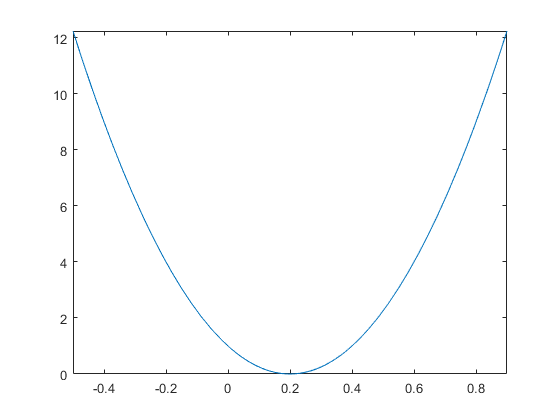

f = @(x) 25.*x.^2-10.*x+1;
fplot(f,[-0.5 0.9]);

**Testarea valorilor **$x_0 =0\ldotp 9$**, **$x_1 =1$**și **$\mathrm{ea}=1e-8$**.**

format long
x0 = 0.9;
x1 = 1;
ea = 1e-8;
diferenta = f(x0)-f(x1)

diferenta =   -3.750000000000000


[z,ni] = secant(f,x0,x1,ea)

z =    0.200000011670111


ni =     37


Pentru valorile $x_0 =0\ldotp 9$, $x_1 =1$și $\mathrm{ea}=1e-8$ se găsește o soluție pentru că în fiecare moment diferența dintre $f\left(x_n \right)-f\left(x_{n-1} \right)$ se apropie de 0, însă este mai mare in modul decat epsilonul mașinii. Acest fapt se datorează valorilor de intrare $x_0$ si $x_1$ pentru care diferența inițială este $f\left(x_0 \right)-f\left(x_1 \right)>0$, dar și erorii absolute. Eroarea absolută permite algoritmului să se oprească înainte să ajungă la valori foarte apropiate între rădăcina curentă și radacina determinată la iterația anterioară. 

Dacă valorile dintre două radăcini consecutive sunt foarte apropiate diferența $f\left(x_n \right)-f\left(x_{n-1} \right)$  ajunge la 0.

**Testarea valorilor **$x_0 =0\ldotp 1$**, **$x_1 =0\ldotp 3$

x0 = 0.1;
x1 = 0.3;
ea = 1e-8;
diferenta = f(x0)-f(x1)

diferenta =      0


[z,ni] = secant(f,x0,x1,ea) % Returneaza eroare. z=NaN

Error using secant (line 32)
numarul maxim de iteratii depasit

Valorile de pornire $x_0 =0\ldotp 1$**, **$x_1 =0\ldotp 3$ au valoarea funcției $f\left(x_0 \right)-f\left(x_1 \right)=0\ldotp 25$ (luând în considerare că $\mathrm{ea}=1e-8$). Acest lucru reprezintă din start o problemă pentru că la calcularea următoarei valori diferența de la numitor este 0, ceea ce înseamnă o împărțire la 0.

Acelasi lucru se întamplă și pentru $x_0 =0\ldotp 15$ și $x_1 =0\ldotp 25$.

x0 = 0.15;
x1 = 0.25;
ea = 1e-8;
diferenta = f(x0)-f(x1)

diferenta =      0


[z,ni] = secant(f,x0,x1,ea) % Returneaza eroare. z=NaN

Error using secant (line 32)
numarul maxim de iteratii depasit

Totuși, pentru unele valori $x_0$ si $x_1$ cu proprietatea (teoretic) $f\left(x_0 \right)=f\left(x_1 \right)$ algoritmul găsește o soluție. Explicația constă în modul în care sistemul efectuează operațiile de înmulțire/adunare și reprezintă numerele. Dacă diferența $f\left(x_n \right)-f\left(x_{n-1} \right)$ este mai mare in modul ca epsilonul mașinii, atunci sistemul găsește o soluție.

Exemplu în care $x_0$ si $x_1$ sunt apropiate de solutie, au $f\left(x_0 \right)=f\left(x_1 \right)$  si totusi se găsește o soluție: $x_0 =0\ldotp 19$ si $x_1 =0\ldotp 21$. Eroarea absolută considerată este în continuare $\mathrm{ea}=1e-8$.

x0 = 0.19;
x1 = 0.21;
diferenta = f(x0)-f(x1)

diferenta =      3.330669073875470e-16


diferenta > eps

ans = logical
   1


ea = 1e-8;
[z,ni] = secant(f,x0,x1,ea)

z =    0.209991455078124


ni =      3


Nu este necesar ca valorile de start să fie dispuse de o parte și de cealaltă a rădăcinii pentru ca metoda să eșueze. Pentru $x_0 =0\ldotp 9$ și $x_1 =0\ldotp 90000000000000001\left(15\;\mathrm{zerouri}\right)$nu găseaște soluția, pentru că diferența $f\left(x_0 \right)-f\left(x_1 \right)$ este mai mică decât epsilonul mașinii, iar sistemul o aproximează la 0.

x0 = 0.9;
x1 = 0.90000000000000001;
diferenta = f(x0)-f(x1)

diferenta =      0


diferenta < eps

ans = logical
   1


ea = 1e-8;
[z,ni] = secant(f,x0,x1,ea) % Returneaza eroare. z=NaN

Error using secant (line 32)
numarul maxim de iteratii depasit

Pentru $x_0 =0\ldotp 9$ si $x_1 =0\ldotp 9000000000000001\left(14\;\mathrm{zerouri}\right)$ se gaseaște o solutie. 

x0 = 0.9;
x1 = 0.9000000000000001;
f(x0)-f(x1)

ans =     -5.329070518200751e-15


ea = 1e-8;
[z,ni] = secant(f,x0,x1,ea) % Returneaza o solutie

z =    0.200000013142589


ni =     37


**Condiția suplimentară **$\left|f\left(x_{\mathrm{curent}} \right)\right|<\mathrm{ea}$ ne asigură că soluția gasită este corectă, adică f(soluția gasită) tinde la 0. 

De exemplu, pentru $x_0 =0\ldotp 17$ și $x_1 =0\ldotp 23$ se gasește o solutie ($x=0\ldotp 2304\ldotp \ldotp \ldotp$), însă valoarea funcției nu este apropiată de 0 ($f\left(x\right)=0\ldotp 023\ldotp \ldotp \ldotp$.). Dacă aplicăm condiția suplimentară metoda secantei nu mai gasește o soluție.

x0 = 0.17;
x1 = 0.23;
ea = 1e-12;
[z,ni] = secant(f,x0,x1,ea) % Gaseste solutie

z =    0.230468750000000


ni =      3


fz = f(z)

fz =    0.023208618164062


[z,ni] = secant_modificat(f,x0,x1,ea) % Returneaza eroare. z=NaN

Error using secant_modificat (line 34)
numarul maxim de iteratii depasit

Aplicarea condiției suplimentare pentru valorile de pornire $x_0 =0\ldotp 9$ și $x_1 =1$.

x0 = 0.9;
x1 = 1;
ea = 1e-12;
[z,ni] = secant_modificat(f,x0,x1,ea)

z =    0.200000002162418


ni =     41


fz = f(z)

fz =      0


fz < ea % f(solutia gasita) este mai mica decat eroarea absoluta

ans = logical
   1
